# **META 4**

21. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    frequenciaDominante     par      entropia     sef      spectralSlope
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    ________________    ______________

22. Calcule, para cada dígito, a STFT, como exemplificado na Figura 5. Use diferentes parametrizações, por exemplo tamanho da janela, sobreposição, número de pontos para cálculo da FFT, etc., e identifique os parâmetros que lhe parecem mais adequados para o objetivo do trabalho. Comente as observações. Nota: utilize a função spectrogram do MATLAB (consulte a documentação associada).

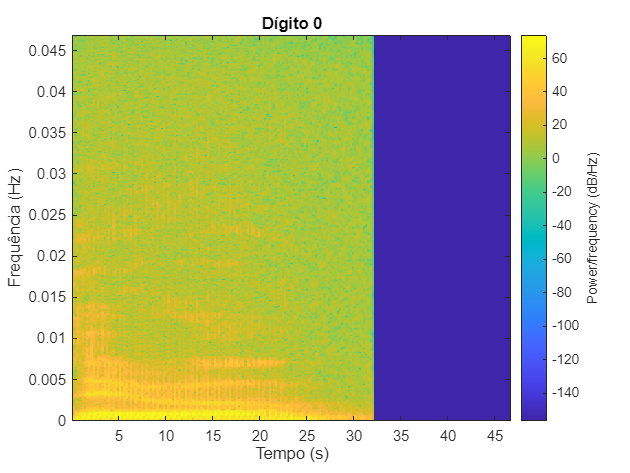

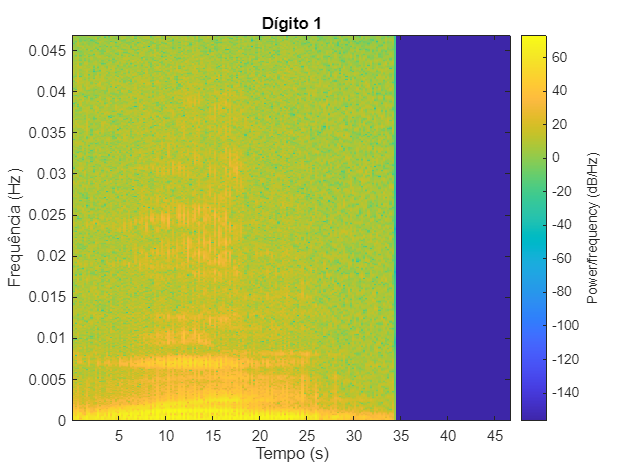

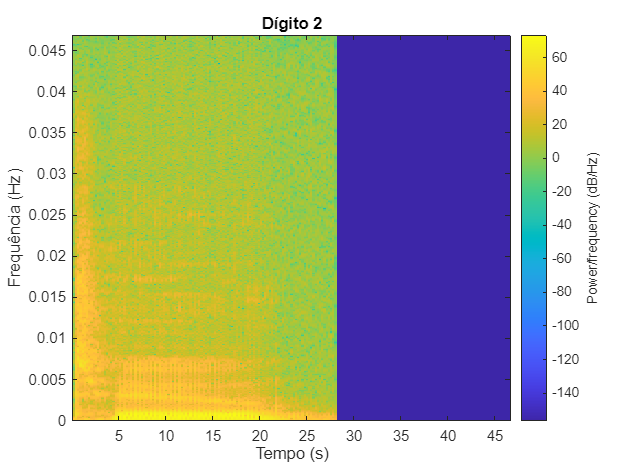

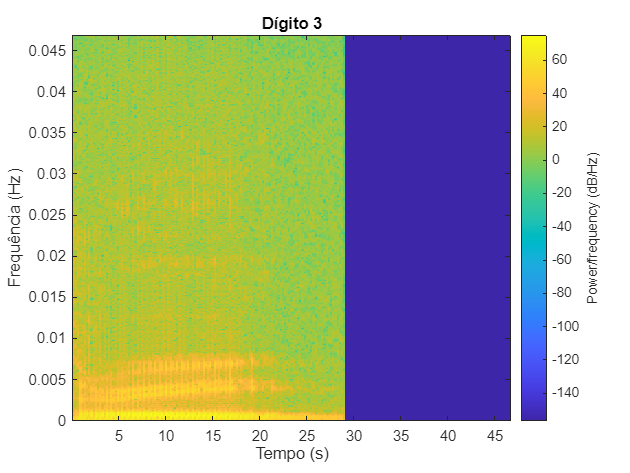

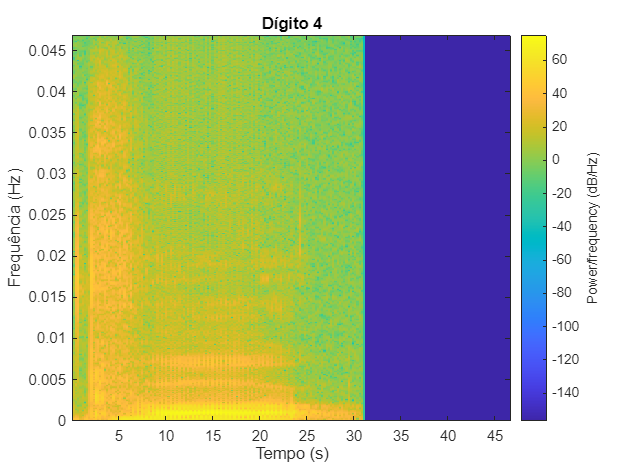

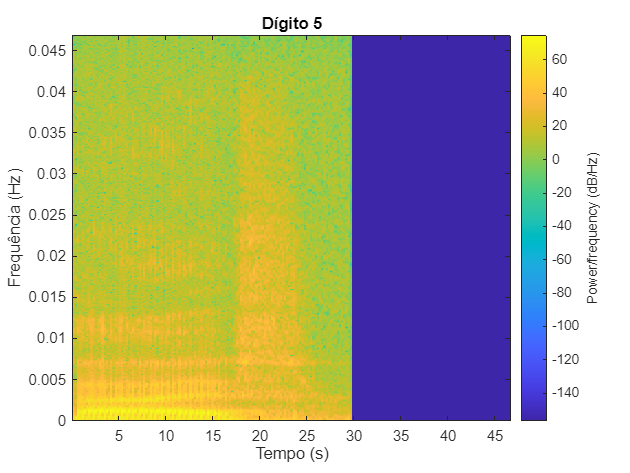

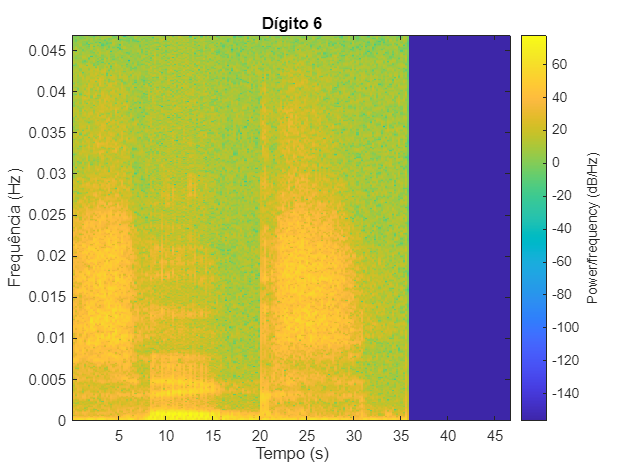

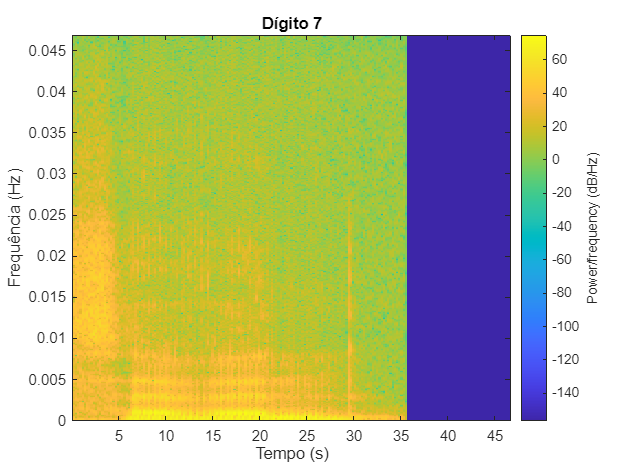

TaxaAmostragem = 38400;
window_tamanho = TaxaAmostragem / 100;
noverlap = window_tamanho / 2;

for digito = 0:9
    idx = find([dados.digito] == digito, 1, 'first'); % Pega um exemplo por dígito
    sinal = dados(idx).sinal;
    fftSinal =  fft(sinal);
    lista_fft = find(fftSinal > 0.8*fftSinal(find(fftSinal,1,"first"))) ;
    nfft = length(fftSinal);
    fs = 1/TaxaAmostragem; % frequencia de amostragem (ajusta conforme o teu caso)
    
    figure;
    spectrogram(sinal, window_tamanho, noverlap, nfft, fs, 'yaxis');
    xlabel('Tempo (s)');
    ylabel('Frequência (Hz)');
    title(['Dígito ', num2str(digito)]);
end

23. Extraia pelo menos 5 características de tempo-frequência em diferentes janelas tempo-frequência que possam ser mais relevantes para a diferenciação dos dígitos. Deverá atualizar a sua estrutura de dados.

for i = 1:length(dados)
    x = dados(i).sinal;

    [s,f,t,p] = spectrogram(x, window_tamanho, noverlap, nfft, fs);
    p = abs(p).^2;

    dados(i).specMeanFreq = mean(mean(p .* f));
    dados(i).specMaxFreq = f(max(mean(p,2)) == mean(p,2));
    dados(i).specBandwidth = sqrt(mean((f - dados(i).specMeanFreq).^2 .* mean(p,2)));
    dados(i).specEntropy = -sum(mean(p,2) .* log(mean(p,2) + eps));
    dados(i).specEnergy = sum(p(:));
end

24. Recorrendo à representação gráfica das características tempo-frequência extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

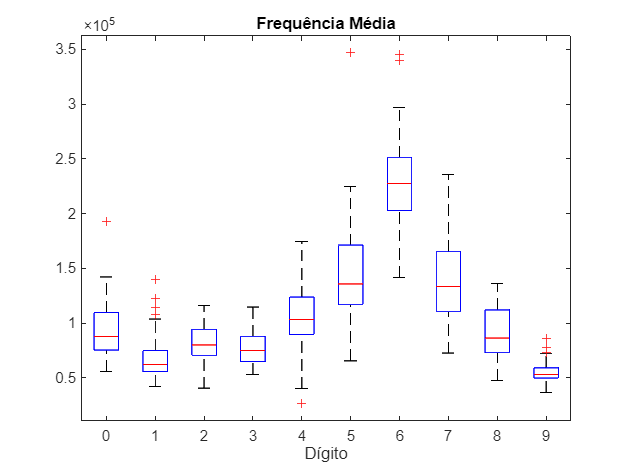

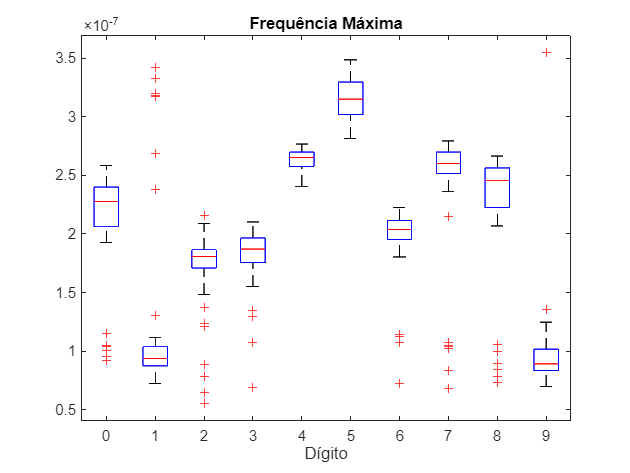

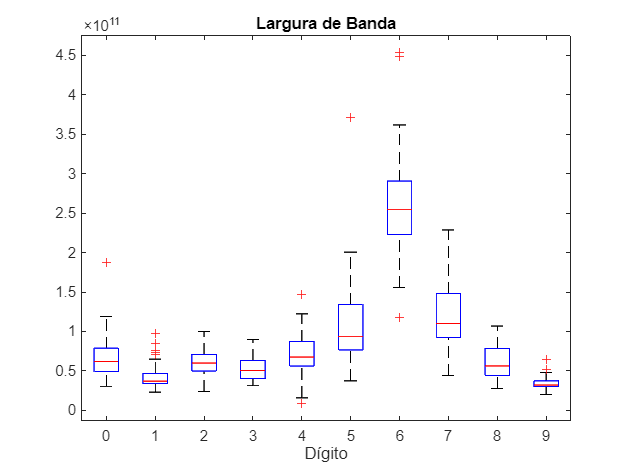

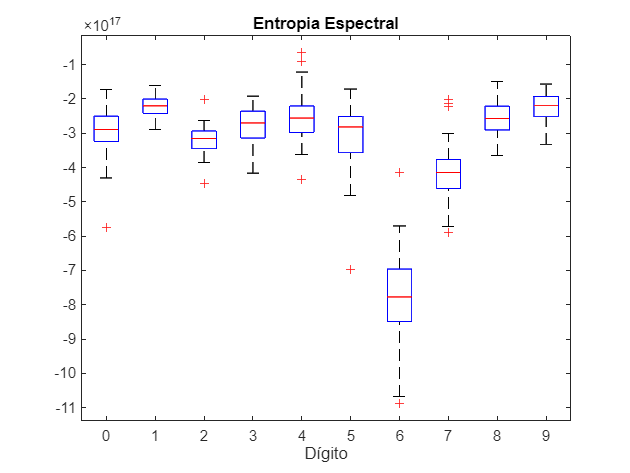

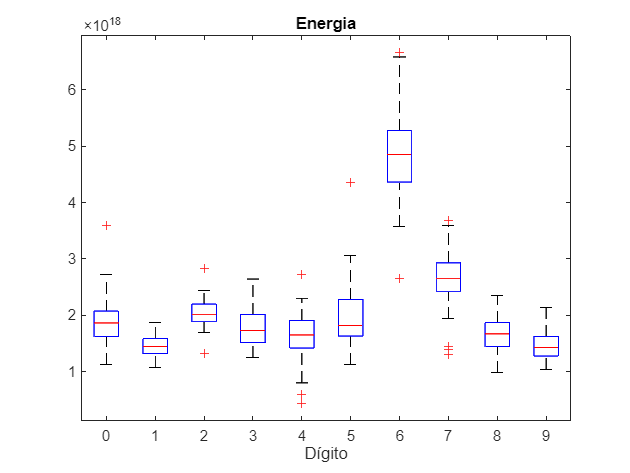

digitos = [dados.digito]';
features = [[dados.specMeanFreq]', [dados.specMaxFreq]', [dados.specBandwidth]', ...
            [dados.specEntropy]', [dados.specEnergy]'];

feature_names = {'Frequência Média', 'Frequência Máxima', ...
                 'Largura de Banda', 'Entropia Espectral', 'Energia'};

for i = 1:5
    figure;
    boxplot(features(:,i), digitos);
    title(feature_names{i});
    xlabel('Dígito');
end

25. Aplicar a Transformada de Wavelet Discreta (DWT) para obter os coeficientes de detalhe e de aproximação, utilizando um nível de decomposição e o tipo de wavelet que considere apropriado. Obter os valores de energia a partir dos coeficientes e representar os resultados, utilizando gráficos semelhantes aos exemplificados na Figura 3. Compare e discuta os resultados obtidos com a STFT e com a DWT.

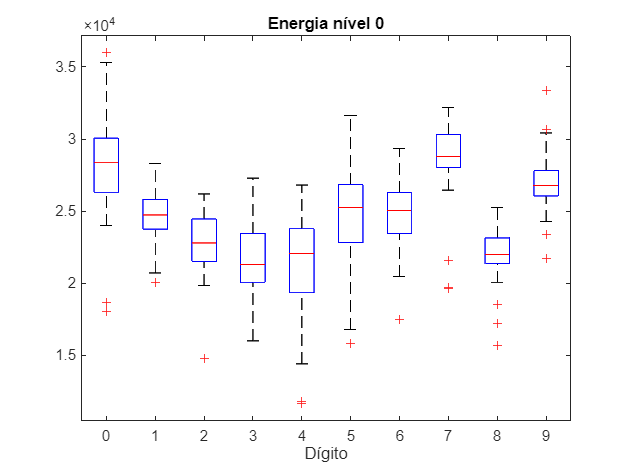

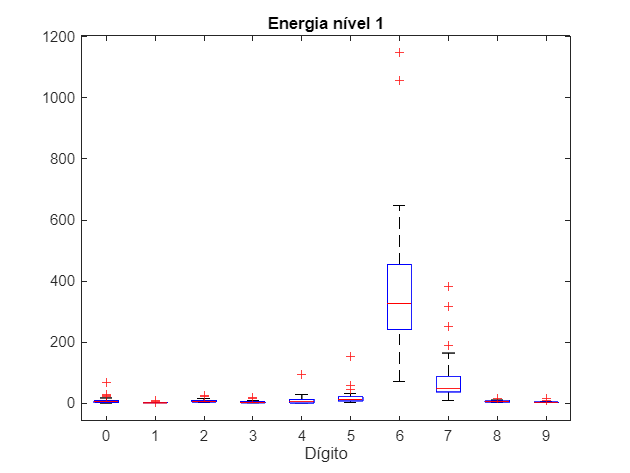

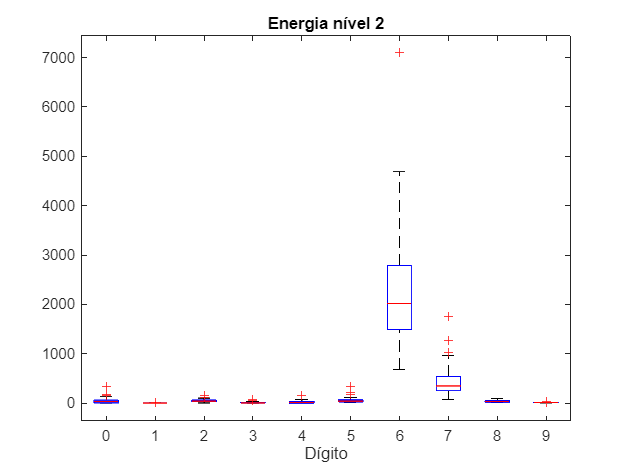

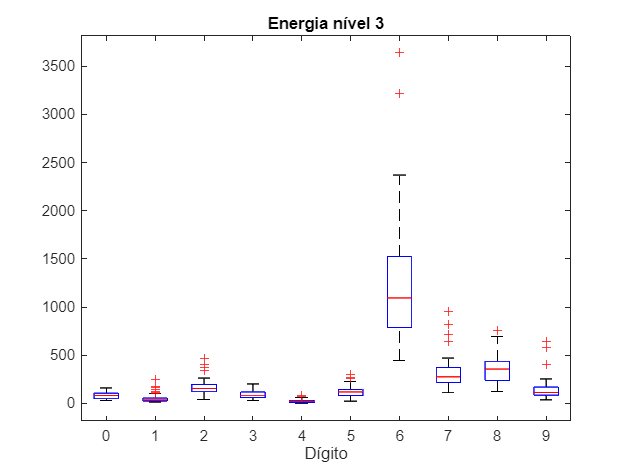

nivel = 3;
wavelet = 'db4';

for i = 1:length(dados)
    x = dados(i).sinal;
    [c,l] = wavedec(x, nivel, wavelet);
    aprox = appcoef(c, l, wavelet);
    detalhes = cell(1, nivel);
    for n = 1:nivel
        detalhes{n} = detcoef(c, l, n);
    end

    energia_aprox = sum(aprox.^2);
    energia_detalhe = cellfun(@(x) sum(x.^2), detalhes);

    dados(i).energia_dwt = [energia_aprox, energia_detalhe];
end

% Gráfico das energias dos coeficientes DWT
energia_matrix = reshape([dados.energia_dwt], nivel+1, []).';

for j = 1:nivel+1
    figure;
    boxplot(energia_matrix(:,j), digitos);
    title(['Energia nível ', num2str(j-1)]);
    xlabel('Dígito');
end

26. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat', 'dados');